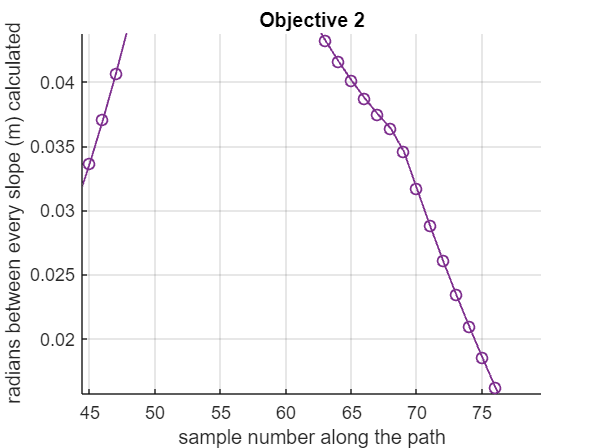

% Lake Etsitty, MENG 451

% This is calculating the angle change for each point, 
% in reference to the previous two points.
% Essentially, finding the slope for every pair of points
% from the Position graph in "bspline_main.mlx" and finding
% their difference in radians.

A = q;
phirad = zeros(1, length(A)-2);

for i = 3:length(A)

    x1 = A(1,(i-2):(i-1))';
    y1 = A(2,(i-2):(i-1))';

    % The equation that solves
    c = [[1; 1]  x1]\y1;   

    % The slope from the first two points in a collection of three points
    slope = c(2);

    x2 = A(1,i-1:i)';
    y2 = A(2,i-1:i)';
    c2 = [[1; 1] x2]\y2;  

    % The slope from the second and third points
    slope2 = c2(2);
    
    % Calculating their difference
    phirad(1,i-2) = atan(slope) - atan(slope2);
    phrad = phirad(1,i-2);
    
    % function "atan" was acting up, so this corrects for that
    if pi > phirad(1,i-2) && phirad(1,i-2) > pi/2
        phirad(1,i-2) = phrad-pi;
    elseif -pi < phirad(1,i-2) && phirad(1,i-2) < -pi/2
        phirad(1,i-2) = phrad+pi;
    end
end


% Plotting the angle change for each point 
% VS the sample number along the path
figure
hold all
grid on
plot(3:length(phirad)+2,(phirad),'o-','linewidth',1,'Color',[0.4940, 0.1840, 0.5560])
xlabel('sample number along the path')

ylabel('radians between every slope (m) calculated')
leng = length(phirad);
xlim([0 leng+1]);

pos02 = round(leng*0.2,0);
pos04 = round(leng*0.4,0);
pos05 = round(leng*0.5,0);
pos06 = round(leng*0.6,0);
pos08 = round(leng*0.8,0);

title('Objective 2')
plot(3,(phirad(1)),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')

plot(pos02,(phirad(1,pos02-2)),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(pos04,(phirad(1,pos04-2)),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(pos05,(phirad(1,pos05-2)),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(pos06,(phirad(1,pos06-2)),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(pos08,(phirad(1,pos08-2)),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')
hold off